clear all
close all
clc

load jPaperData2.mat
% dataTemp = [seedVal,is1,is2,is3,is4,is5,is6,is7,is8,  seedVal,is9,is10,is11,is12,is13,is14,is15,is16]
stabilizationExamples = [];
dissipativationExamples = [];
for i = 1:1:length(data)
    if all(data(i,2:5)==[0 1 1 1]) & all(data(i,11:14)==[0 1 1 1])
        stabilizationExamples = [stabilizationExamples,data(i,1)];
        if all(data(i,8:9)==[1 1]) & all(data(i,17:18)==[1 1])
            data(i,:)
            dissipativationExamples = [dissipativationExamples, data(i,1)];
        end
    end
end

ans =    248     0     1     1     1     0     0     1     1   248     0     1     1     1     0     0     1     1


ans =    263     0     1     1     1     0     0     1     1   263     0     1     1     1     0     0     1     1


ans =    333     0     1     1     1     0     0     1     1   333     0     1     1     1     0     0     1     1


ans =    543     0     1     1     1     0     0     1     1   543     0     1     1     1     0     0     1     1


ans =    660     0     1     1     1     0     0     1     1   660     0     1     1     1     0     0     1     1


ans =    853     0     1     1     1     0     0     1     1   853     0     1     1     1     0     0     1     1


% seedVals = stabilizationExamples
seedVals = dissipativationExamples

seedVals =    248   263   333   543   660   853


seedVal = 333 % 263

seedVal = 333

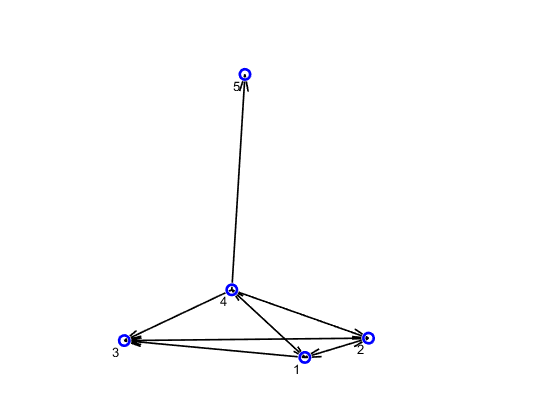

% data(seedVal,:)
rng(seedVal) 

%% Create a network object
network = Network(0);

% Number of subsystems
numOfSubsystems = 5; % 5
dimentionOfSpace = 2;
sizeOfSpace = 1;
communicationRadius = 0.8; %0.9

% subsystem dims
for i = 1:1:numOfSubsystems
    dims{i}.n = 2; % x
    dims{i}.p = 1; % u
    dims{i}.q = 1; % w  
    dims{i}.m = 1; % y
    dims{i}.l = 1; % z 
end

% Diagonal matrices out of Network Matrices: A,B,C,D,E,F,G,H,J,Q,S,R 
% (1 if true, -1 % if zero and 0 if false)
diags = [0,1,1,-1,0,1,1,1,1]; % respectively for 

% Create the network and plot it
network = network.loadARandomNetwork(numOfSubsystems,dimentionOfSpace,sizeOfSpace,communicationRadius,dims,diags);
% network.shiftLocations();
close all
network.drawNetwork(1,false);


% Get network matrices
[A,B,C,D,E,F,G,H,J,x] = network.getNetworkMatrices();
n = size(A,1);
p = size(B,2);
q = size(E,2);

% Generate Q,S,R matrices
dissFrom = 'w';    % Options: 'u', 'w'
dissTo = 'y';      % Options: 'y', 'z'
dissType = 'strictly passive';     % Options: strictly passive([IFP, OFP]), passive, L2G(gamma), random 
dissArgs = [0.2,0.2]; %[0,0.01]
% dissType = 'passive';
% dissArgs = 0;
[Q,S,R] = network.getSomeQSRMatrices(dissFrom,dissTo,dissType,dissArgs); 
network.storeQSRMatrices(Q,S,R); % Store information locally at each sub-system

Stability Analysis and Stabilization

% % %     Central Stability Based Concepts
% addpath('C:\Program Files\Mosek\9.3\toolbox\R2015a')
solverOptions = sdpsettings('solver','mosek','verbose',0);

rng(seedVal);

% % % % Stability Analysis
isStable = network.centralizedStabilityAnalysis(solverOptions)

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1669831 (R2021a) Update 2'
       yalmiptime: 0.3225
       solvertime: 0.0105
             info: 'Numerical problems (MOSEK)'
          problem: 4


isStable = logical
   0



% % % % Stabilization using FSF control
[KStab,isFSFStabilizable] = network.centralizedFSFStabilization(solverOptions)

KStab =    -0.0802   -1.5665   -0.1967    0.5107         0         0   -1.7758   -0.6057         0         0
   -0.1737   -0.1227    4.8072   -3.0771         0         0   -0.2598    0.0414         0         0
   -0.0831   -0.1179   -0.0571   -0.0674   29.8865    5.0680    0.2480   -0.1095         0         0
    1.2730    0.7885         0         0         0         0  -10.4960   -6.8491         0         0
         0         0         0         0         0         0    0.0348   -0.0390    1.3661    2.2498


isFSFStabilizable = logical
   1



% % % % Stable observer design
[LStab,isObserverStable] = network.centralizedStableObserverDesign(solverOptions)

LStab =     1.4652    0.0364         0   -0.3438         0
   -0.1275   -0.1299         0    0.5433         0
    0.0318   -2.3970         0   -0.4094         0
    0.0254    4.1446         0   -0.0123         0
   -0.0125    0.0398   11.6421   -0.1169         0
    0.0430   -0.0639    3.8164    0.6103         0
   -0.4354         0         0   12.6938         0
   -0.9909         0         0   34.7094         0
         0         0         0   -0.0942    0.3604
         0         0         0    0.0532   -2.8858


isObserverStable = logical
   1



% % % % Stabilization using DOF control
[AcStab,BcStab,CcStab,DcStab,isDOFStabilizable] = network.centralizedDOFStabilization(solverOptions)

AcStab =    -1.9572    2.8809   -0.1098   -0.0199         0         0    0.2881   -3.7557         0         0
  -27.3792   13.9243    0.0112   -0.6735         0         0    0.6338    1.9243         0         0
    0.2219   -0.2035   -3.7923  -12.1070         0         0    0.0960   -2.0836         0         0
   -0.0020    0.1540    4.1249   -1.6442         0         0   -0.0473    1.0181         0         0
    0.0239    0.0064    0.0151   -0.0030   46.0512 -112.2839   -0.0096    0.2097         0         0
   -0.1598   -0.0430   -0.0609   -0.0378   24.9860  -63.9932    0.0644   -1.4000         0         0
   -2.0301   -0.3494         0         0         0         0   -0.3143   66.6726         0         0
    0.4828   -0.1842         0         0         0         0   -1.4683   -9.5706         0         0
         0         0         0         0         0         0    0.0003   -0.0072   -0.3352    3.5789
         0         0         0         0         0         0    0.0001   -0.0029  

BcStab =    -5.0507   -0.8217         0    4.2408         0
  -65.1666    1.1166         0   21.7082         0
    0.0490   -7.8700         0    0.3016         0
   -0.0657   50.3859         0    0.0099         0
   -0.0158    0.1584  -78.2913   -0.1817         0
    0.1055   -0.2265  -99.2709    1.2132         0
    0.0358         0         0  -39.1086         0
    0.9052         0         0  -52.0158         0
         0         0         0    0.8554    7.7086
         0         0         0    0.3388   14.4757


CcStab =     2.0897   -1.3816   -0.0050    0.0517         0         0   -0.0411   -0.3560         0         0
    0.0443   -0.0061   -0.0834   -1.6395         0         0    0.0017   -0.0366         0         0
    0.0201    0.0054    0.0078    0.0079    2.4493   -5.9069   -0.0041    0.0883         0         0
   -0.2661   -0.0187         0         0         0         0    0.1387    7.5069         0         0
         0         0         0         0         0         0   -0.0015    0.0315    0.0037   -0.3814


DcStab =     6.7771    0.0456         0   -3.4879         0
    0.0498    6.5754         0   -0.4155         0
    0.0271   -0.0284   -0.0534    0.3943         0
   -0.0899         0         0   -0.1715         0
         0         0         0    0.0552    0.0019


isDOFStabilizable = logical
   1



rng(seedVal);

% % % % Stability Analysis
isStableD = network.decentralizedStabilityAnalysis([],solverOptions)

Checking stability at: 1 after .
Error: det(tildeW_ii) low
Data saved 1 after .
LMI is not feasible at: 1 after .


isStableD = logical
   0



% % % % Stabilization using FSF control
[KStabD,isFSFStabilizableD] = network.decentralizedFSFStabilization([],solverOptions)

Stabilizing at: 1 after .
Data saved 1 after .
Stabilizing at: 2 after 1.
Data at 2 after 1.
Data saved 2 after 1.
Stabilizing at: 3 after 1  2.
Data at 3 after 1  2.
Data saved 3 after 1  2.
Stabilizing at: 4 after 1  2  3.
Data at 4 after 1  2  3.
Data saved 4 after 1  2  3.
Stabilizing at: 5 after 1  2  3  4.
Data at 5 after 1  2  3  4.
Data saved 5 after 1  2  3  4.


KStabD =    -0.2957   -1.5228   -0.1729    0.5740         0         0   -0.9729    0.1139         0         0
   -0.1682   -0.0427    5.3692   -3.9162         0         0   -0.2336    0.0405         0         0
   -0.0831   -0.1179   -0.0571   -0.0674   32.4494    5.4294    0.2480   -0.1095         0         0
    1.0232    0.2787         0         0         0         0  -12.9739   -8.0814         0         0
         0         0         0         0         0         0    0.0348   -0.0390    1.7528    2.8029


isFSFStabilizableD = logical
   1



% % % % Stable observer design
[LStabD,isObserverStableD] = network.decentralizedStableObserverDesign([],solverOptions)

Stabilizing at: 1 after .
Data saved 1 after .
Stabilizing at: 2 after 1.
Data at 2 after 1.
Data saved 2 after 1.
Stabilizing at: 3 after 1  2.
Data at 3 after 1  2.
Data saved 3 after 1  2.
Stabilizing at: 4 after 1  2  3.
Data at 4 after 1  2  3.
Data saved 4 after 1  2  3.
Stabilizing at: 5 after 1  2  3  4.
Data at 5 after 1  2  3  4.
Data saved 5 after 1  2  3  4.


LStabD =     0.3060   -0.0423         0   -0.6400         0
   -0.4270   -0.2068         0    1.3951         0
    0.0598   -3.4029         0   -0.4094         0
   -0.0077    4.5958         0   -0.0123         0
   -0.0125   -0.0587   12.2189   -0.1169         0
    0.0430   -0.0804    3.6156    0.6103         0
   -0.5768         0         0   35.6019         0
   -1.5909         0         0   97.0478         0
         0         0         0   -0.0942    0.5888
         0         0         0    0.0532   -3.5854


isObserverStableD = logical
   1



% % % % Stabilization using DOF control
[AcStabD,BcStabD,CcStabD,DcStabD,isDOFStabilizableD] = network.decentralizedDOFStabilization([],solverOptions) 

Stabilizing at: 1 after .
Data saved 1 after .
Stabilizing at: 2 after 1.
Data at 2 after 1.
Symmetry Error !!! Magnitude:2.4435e-16
Symmetry Error !!! Magnitude:5.3314e-26
Data saved 2 after 1.
Stabilizing at: 3 after 1  2.
Data at 3 after 1  2.
Symmetry Error !!! Magnitude:6.3047e-16
Data saved 3 after 1  2.
Stabilizing at: 4 after 1  2  3.
Data at 4 after 1  2  3.
Symmetry Error !!! Magnitude:6.8046e-16
Data saved 4 after 1  2  3.
Stabilizing at: 5 after 1  2  3  4.
Data at 5 after 1  2  3  4.
Symmetry Error !!! Magnitude:2.4044e-15
Data saved 5 after 1  2  3  4.


AcStabD =    -2.0074    3.7395   -0.0794   -0.3186         0         0    0.1751   -1.9334         0         0
   -8.6968    3.8658    0.0419   -0.8674         0         0    0.0099   -2.9209         0         0
    0.1424   -0.1982   -4.7429  -16.0326         0         0    0.2228   -3.0944         0         0
    0.0185    0.1936    3.7289   -1.2250         0         0   -0.0410   -0.5634         0         0
    0.0567    0.1189   -0.0011   -0.0028   45.3574 -183.6804    0.0008   -0.0309         0         0
   -0.0591    0.0419   -0.0563   -0.1310   13.8408  -62.3236    0.0548   -2.5776         0         0
   -2.7966   -0.2254         0         0         0         0   -0.3320  151.6853         0         0
    0.4269    0.0869         0         0         0         0   -1.4208  -14.2647         0         0
   -0.1472    0.0439   -0.0818   -0.2423    0.1112   -0.3392    0.0003   -0.0123   -0.4010    4.8470
    0.0029   -0.0272   -0.0121    0.0211   -0.0192    0.0090    0.0001   -0.0033 

BcStabD =    -1.1446    0.1860         0    0.1590         0
   -4.7560    0.6398         0  -10.9954         0
   -0.0862   -7.9607         0   -1.8775         0
   -0.0338   14.3566         0    1.5286         0
    0.0009    0.0016  -13.9331    0.0078         0
    0.0465    0.0835  -27.6991    0.5315         0
    0.1211         0         0  -30.2319         0
    0.2082         0         0  -26.8150         0
         0         0         0    0.3199    3.2345
         0         0         0    0.1209    5.1118


CcStabD =     1.5544   -1.3722   -0.0116    0.1910         0         0    0.0130    0.0556         0         0
    0.1042    0.0108   -0.7423   -5.7318         0         0    0.0024   -0.3718         0         0
    0.0279    0.0484    0.0189    0.0438    7.0277  -28.1551   -0.0079    0.3730         0         0
   -0.8897   -0.0861         0         0         0         0    0.2428   31.2996         0         0
         0         0         0         0         0         0   -0.0028    0.1316    0.0111   -1.5426


DcStabD =     2.0565    0.0631         0   -1.5392         0
    0.0000    2.9239         0   -0.4009         0
    0.0271   -0.0635    2.1875    0.3945         0
   -0.0067         0         0   -3.2696         0
         0         0         0    0.0551   -0.0913


isDOFStabilizableD = logical
   1


Dissipativity Analysis and Dissipativation

dissFrom = 'w'; dissTo = 'y';  
dissType = 'strictly passive'; dissArgs = [0.2,0.2];
% dissType = 'passive'; dissArgs = [];
[Q,S,R] = network.getSomeQSRMatrices(dissFrom,dissTo,dissType,dissArgs) % dissFrom,dissTo,dissType,dissArgs

Q =    -0.2000         0         0         0         0
         0   -0.2000         0         0         0
         0         0   -0.2000         0         0
         0         0         0   -0.2000         0
         0         0         0         0   -0.2000


S =     0.5000         0         0         0         0
         0    0.5000         0         0         0
         0         0    0.5000         0         0
         0         0         0    0.5000         0
         0         0         0         0    0.5000


R =    -0.2000         0         0         0         0
         0   -0.2000         0         0         0
         0         0   -0.2000         0         0
         0         0         0   -0.2000         0
         0         0         0         0   -0.2000


network.storeQSRMatrices(Q,S,R);

% % % % Dissipativity Analysis
isDissipative = network.centralizedDissipativityAnalysis(dissFrom,dissTo,Q,S,R,solverOptions)

isDissipative = logical
   0



% % % % Dissipativation using FSF control
[KDiss,isFSFDissipative] = network.centralizedFSFDissipativation(dissFrom,dissTo,Q,S,R,solverOptions)

KDiss = 	1.0e+08 *

    0.1462   -0.0528   -0.0000    0.0004         0         0    0.0000   -0.0003         0         0
    0.9374   -0.0017    0.0004   -0.3322         0         0   -0.0009    0.0015         0         0
    0.0002   -0.0001   -0.0000    0.0004    0.0495    0.0030   -0.0002   -0.0000         0         0
   -1.7847    0.0079         0         0         0         0   -0.8619   -0.0016         0         0
         0         0         0         0         0         0    0.0000    0.0000    0.0110    0.0149


isFSFDissipative = logical
   0



dissFrom = 'w'; dissTo = 'z';  
dissType = 'strictly passive'; dissArgs = [0.2,0.2];
[Q,S,R] = network.getSomeQSRMatrices(dissFrom,dissTo,dissType,dissArgs) % dissFrom,dissTo,dissType,dissArgs

Q =    -0.2000         0         0         0         0
         0   -0.2000         0         0         0
         0         0   -0.2000         0         0
         0         0         0   -0.2000         0
         0         0         0         0   -0.2000


S =     0.5000         0         0         0         0
         0    0.5000         0         0         0
         0         0    0.5000         0         0
         0         0         0    0.5000         0
         0         0         0         0    0.5000


R =    -0.2000         0         0         0         0
         0   -0.2000         0         0         0
         0         0   -0.2000         0         0
         0         0         0   -0.2000         0
         0         0         0         0   -0.2000


network.storeQSRMatrices(Q,S,R);

% % % % Dissipative observer design
[LDiss,isObserverDissipative] = network.centralizedDissipativeObserverDesign(dissFrom,dissTo,Q,S,R,solverOptions)

LDiss =     1.5373   -1.3414         0   -0.4084         0
   -0.1712    1.2192         0    0.6386         0
   -0.5056   -2.4373         0   -0.4151         0
    0.8264    4.2170         0   -0.0192         0
   -0.0099    0.0454   11.6903   -0.1234         0
    0.0432   -0.0623    3.8317    0.6066         0
   -0.4086         0         0   13.9292         0
   -0.9304         0         0   38.1163         0
         0         0         0   -0.0939    0.3445
         0         0         0    0.0588   -3.0085


isObserverDissipative = logical
   1



% % % % Dissipativation using DOF control
[AcDiss,BcDiss,CcDiss,DcDiss,isDOFDissipative] = network.centralizedDOFDissipativation(dissFrom,dissTo,Q,S,R,solverOptions) 

AcDiss = 	1.0e+03 *

   -0.0023    0.0029    0.0001   -0.0041         0         0    0.0002   -0.0071         0         0
   -0.0082   -0.0005   -0.0002   -0.0035         0         0    0.0002    0.0062         0         0
   -0.0022    0.0015   -0.0071   -0.0931         0         0    0.0001   -0.0106         0         0
    0.0015   -0.0011    0.0011   -0.0391         0         0   -0.0000    0.0055         0         0
   -0.0003   -0.0001   -0.0001   -0.0004    0.0029   -1.3970    0.0000   -0.0039         0         0
   -0.0005   -0.0001   -0.0002   -0.0002   -0.0017   -0.4223    0.0001   -0.0109         0         0
   -0.0022   -0.0003         0         0         0         0   -0.0017    0.6901         0         0
    0.0000   -0.0002         0         0         0         0   -0.0013   -0.0952         0         0
         0         0         0         0         0         0   -0.0000   -0.0004   -0.0004    0.0102
         0         0         0         0         0         0    0.0000

BcDiss =    -3.8062    6.3658         0   14.4745         0
    0.1084   -4.0997         0    4.2212         0
   -7.3781  -66.3618         0    2.2687         0
    5.0284   61.3721         0    2.2802         0
   -0.2071   -1.3364  -90.5059   -2.8322         0
    0.1734   -3.0625 -176.4148    1.7181         0
    0.2223         0         0 -189.5455         0
    0.6325         0         0 -156.1177         0
         0         0         0    0.8477   -1.9108
         0         0         0    0.1738   23.8372


CcDiss =     0.2517    0.1285   -0.0150    0.9011         0         0   -0.0058   -0.8591         0         0
   -0.0007    0.0003   -0.5177   -9.1908         0         0    0.0002   -0.0157         0         0
    0.0143    0.0028    0.0020    0.0000    0.1566  -49.1384   -0.0007    0.1916         0         0
   -0.0289    0.0059         0         0         0         0   -0.0365   29.4809         0         0
         0         0         0         0         0         0   -0.0002    0.0610    0.0109   -1.4698


DcDiss =     0.2480   -0.7521         0   -0.9909         0
   -0.0002   -0.3517         0   -0.1158         0
    0.0187   -0.0119    1.9728    0.2959         0
   -0.0314         0         0   -4.7276         0
         0         0         0    0.0347    1.6447


isDOFDissipative = logical
   1





dissFrom = 'w'; dissTo = 'y';  
dissType = 'strictly passive'; dissArgs = [0.2,0.2];
[Q,S,R] = network.getSomeQSRMatrices(dissFrom,dissTo,dissType,dissArgs); % dissFrom,dissTo,dissType,dissArgs
network.storeQSRMatrices(Q,S,R);

% % % % Dissipativity Analysis
isDissipativeD = network.decentralizedDissipativityAnalysis(dissFrom,dissTo,[],solverOptions)

Checking QSR-Dissipativity at: 1 after .
Data saved 1 after .
LMI is not feasible at: 1 after .


isDissipativeD = logical
   0



% % % % Dissipativation using FSF control
[KDissD,isFSFDissipativeD] = network.decentralizedFSFDissipativation(dissFrom,dissTo,[],solverOptions)

Dissipativating at: 1 after .
Data saved 1 after .
Not stabilizable at: 1 after .


KDissD =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


isFSFDissipativeD = logical
   0



dissFrom = 'w'; dissTo = 'z';  
dissType = 'strictly passive'; dissArgs = [0.2,0.2];
[Q,S,R] = network.getSomeQSRMatrices(dissFrom,dissTo,dissType,dissArgs) % dissFrom,dissTo,dissType,dissArgs

Q =    -0.2000         0         0         0         0
         0   -0.2000         0         0         0
         0         0   -0.2000         0         0
         0         0         0   -0.2000         0
         0         0         0         0   -0.2000


S =     0.5000         0         0         0         0
         0    0.5000         0         0         0
         0         0    0.5000         0         0
         0         0         0    0.5000         0
         0         0         0         0    0.5000


R =    -0.2000         0         0         0         0
         0   -0.2000         0         0         0
         0         0   -0.2000         0         0
         0         0         0   -0.2000         0
         0         0         0         0   -0.2000


network.storeQSRMatrices(Q,S,R);

% % % % Dissipative observer design
[LDissD,isObserverDissipativeD] = network.decentralizedDissipativeObserverDesign(dissFrom,dissTo,[],solverOptions)

Dissipativating at: 1 after .
Data saved 1 after .
Dissipativating at: 2 after 1.
Data at 2 after 1.
Symmetry Error !!! Magnitude:7.2164e-16
Data saved 2 after 1.
Dissipativating at: 3 after 1  2.
Data at 3 after 1  2.
Data saved 3 after 1  2.
Dissipativating at: 4 after 1  2  3.
Data at 4 after 1  2  3.
Data saved 4 after 1  2  3.
Dissipativating at: 5 after 1  2  3  4.
Data at 5 after 1  2  3  4.
Data saved 5 after 1  2  3  4.


LDissD =     0.4679   -1.4124         0   -0.7256         0
   -0.6043    1.3423         0    1.2400         0
   -0.4691   -3.4663         0   -0.4211         0
    0.7012    4.6636         0   -0.0117         0
   -0.0119   -0.0593   12.3147   -0.1260         0
    0.0416   -0.0778    3.5598    0.6082         0
   -0.2112         0         0   22.3602         0
   -0.5217         0         0   61.0226         0
         0         0         0   -0.0916    0.5771
         0         0         0    0.0556   -3.7454


isObserverDissipativeD = logical
   1



% % % % Stabilization using DOF control
[AcDissD,BcDissD,CcDissD,DcDissD,isDOFDissipativeD] = network.decentralizedDOFDissipativation(dissFrom,dissTo,[],solverOptions) 

Stabilizing at: 1 after .
Data saved 1 after .
Stabilizing at: 2 after 1.
Data at 2 after 1.
Symmetry Error !!! Magnitude:4.0574e-16
Symmetry Error !!! Magnitude:4.5103e-16
Data saved 2 after 1.
Stabilizing at: 3 after 1  2.
Data at 3 after 1  2.
Symmetry Error !!! Magnitude:9.6697e-15
Data saved 3 after 1  2.
Stabilizing at: 4 after 1  2  3.
Data at 4 after 1  2  3.
Symmetry Error !!! Magnitude:4.3749e-14
Data saved 4 after 1  2  3.
Stabilizing at: 5 after 1  2  3  4.
Data at 5 after 1  2  3  4.
Symmetry Error !!! Magnitude:6.4386e-14
Data saved 5 after 1  2  3  4.


AcDissD = 	1.0e+03 *

   -0.0017    0.0029    0.0001   -0.0041         0         0    0.0001   -0.0135         0         0
   -0.0060   -0.0003   -0.0001   -0.0060         0         0    0.0000   -0.0514         0         0
   -0.0023    0.0014   -0.0068   -0.1033         0         0    0.0001    0.0247         0         0
    0.0014   -0.0011    0.0015   -0.0429         0         0   -0.0000   -0.0226         0         0
   -0.0000    0.0003   -0.0001   -0.0018    0.0030   -0.8061    0.0000    0.0043         0         0
   -0.0005    0.0001   -0.0001   -0.0014   -0.0016   -0.2653    0.0000   -0.0247         0         0
   -0.0002    0.0001         0         0         0         0   -0.0021    1.7027         0         0
    0.0001    0.0001         0         0         0         0   -0.0015   -0.2520         0         0
   -0.0003    0.0001   -0.0000   -0.0005    0.0000   -0.0006   -0.0000   -0.0010   -0.0005    0.0101
    0.0000   -0.0001   -0.0000    0.0001   -0.0000    0.0000    0.000

BcDissD =    -0.6075    3.9957         0   25.6252         0
    0.8467   -2.0520         0    0.1778         0
   -3.5737  -60.4670         0   -9.5874         0
    2.1271   60.4620         0    7.8274         0
    0.0102    0.1859  -84.9709   -1.7633         0
    0.2963    0.5858 -186.4572    2.6200         0
    0.4819         0         0 -367.2026         0
    0.1406         0         0 -305.7964         0
         0         0         0    0.7435    0.0982
         0         0         0    0.1044   22.8167


CcDissD =     0.5699    0.1502   -0.0098    2.5901         0         0   -0.0085  -10.0721         0         0
    0.0031    0.0008   -0.4991  -10.7123         0         0    0.0004    0.8453         0         0
    0.0244    0.0387    0.0018   -0.0198    0.1561  -27.3417   -0.0003    1.1728         0         0
   -0.0268   -0.0025         0         0         0         0   -0.0324   52.9337         0         0
         0         0         0         0         0         0   -0.0001    0.1178    0.0124   -1.6210


DcDissD =     0.2052   -0.3404         0   -1.6082         0
   -0.0000   -0.3728         0   -0.3301         0
    0.0252   -0.0621    2.3176    0.3190         0
   -0.0148         0         0   -6.6701         0
         0         0         0    0.0387    1.6306


isDOFDissipativeD = logical
   1




%% saved at after running JSimResultsModel2.slx as jPaperDataDiss.mat